# Robot Mobility: Assignment 1

Submitted by: Sushanth Jayanth

## Q 2. 

#### 2 The system to be modelled has the following matrices

% syms C_af C_ar l_f l_r I_z V_x m
I_z = 2873;
V_x = 30;
m = 1573;
C_af = 80000;
C_ar = 80000;
l_r = 1.58;
l_f = 1.1;

A = [[0,1,0,0];[0, (2*(-C_af+C_ar))/(m*V_x), (2*(C_af+C_ar))/m, (-2*(C_af*l_f - C_ar*l_r))/(m*V_x)];
    [0,0,0,1];[0, (-2*(C_af*l_f + C_ar*l_r))/(I_z*V_x), (2*(C_af*l_f - C_ar*l_r))/I_z, (-2*(C_af*l_f*l_f - C_ar*l_r*l_r))/(I_z*V_x)]]

B_1 = [0; ((2*C_af)/m); 0; (2*C_af*l_f)/m]

B_2 = [0; (-2*(C_af*l_f + C_ar*l_r))/(m*V_x); 0; (-2*(C_af*l_f*l_f - C_ar*l_r*l_r))/(I_z*V_x)];

####  **2 d. Finding the optimal feedback control gain **

Q = [[1,0,0,0];[0,1,0,0];[0,0,1,0];[0,0,0,1]];
R = 10;

A =          0    1.0000         0         0
         0         0  203.4329    1.6275
         0         0         0    1.0000
         0   -4.9751  -26.7316    2.3880



K = lqr(A, B_1, Q, R)

B_1 =          0
  101.7165
         0
  111.8881


Define the trajectory parameters

The desired trajectory was divided into three zones as seen below:

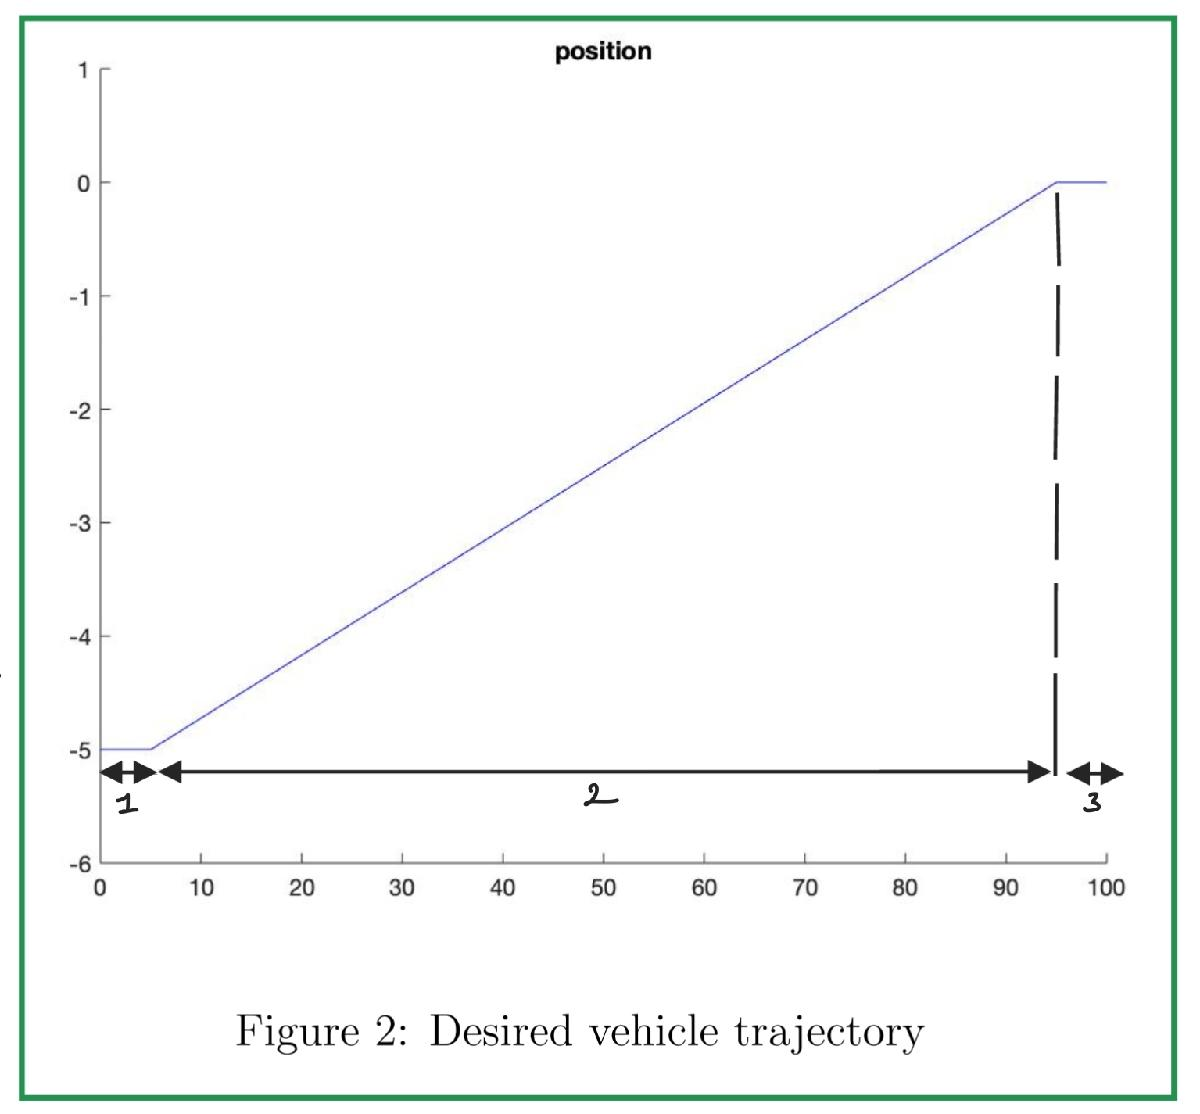

The time taken to complete each zone is calculated below:

t_1 = 5/V_x
t_2 = 90/V_x
% zone 3 was extended to observe convergence times
% zone 3 which is originally 5 metres, was extended to 30 metres
t_3 = 30/V_x

% Combined timespan

K =     0.3162    0.4493    7.1666    0.1597


timespan = 0 : 0.01 : (t_1 + t_2 + t_3);

% Creating the Desired Trajectory

x_des = []

t_1 = 0.1667

y_des = []

t_2 = 3


for t = timespan
    % save the x_position at every timestep

t_3 = 1

    x_des(end+1) = V_x*t;

    % save the y_position at every timestep
    if (round(t_1,2) < t) && (t < round((t_1+t_2),2))
        y_des(end+1) = 0.0556*(x_des(end)-5) - 5;
    
    elseif (t > round((t_1+t_2),2)) || (t > round((t_1+t_2),2) - 0.001)


x_des =

     []



        y_des(end+1) = 0;


y_des =

     []



    else
        y_des(end+1) = -5;
    end
end

plot(x_des, y_des)

Create the inputs psi_des

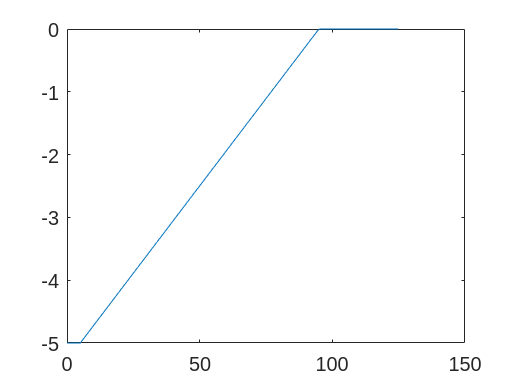

psi_des = [];

left_turn = 0;
right_turn = 0;

for t = timespan
    if (round(t_1,2) < t) && (t < round((t_1+0.01),2)) && left_turn == 0
        % turn left
        psi_des(end+1) = -30;
        left_turn = 1;
    
    elseif (round(t_2,2) < t) && (t < round((t_2+0.01),2)) && right_turn == 0
        psi_des(end+1) = 30;
        right_turn = 1;
    
    else
        psi_des(end+1) = 0;
    end
end

 Using the above feedback control to plot the state of the linearized system

% define three initial state vector x_0
x_0 = [0; 0; 0; 0];

[t,e] = ode45(@(t,e)(lane_controller(e, A, B_1, B_2, K, t_1, t_2, t)),timespan,x_0);

Not enough input arguments.

Error in problem_set_1>lane_controller (line 108)
y_des = offset+amp*square(2*pi*freq.*t,duty);

Error in problem_set_1 (line 51)
[t,e] = ode45(@(t,e)(lane_controller(e, A, B_1, B_2, t)), timespan, x_0);

Error in odearguments (<a h


% since y_des is in inches and x5 is in metres, we multiply the x5 plot
plot(t, e)
title('Error of Lane Tracking System')
ylabel('Amplitude')
xlabel('time(s)')

**--------------------------------------------------------------------------------------------------------------------------------------------------------------------------**

function e_dot = lane_controller (e, A, B1, B2, K, t_1, t_2, t)

Invalid expression. Check for missing multiplication operator, missing or unbalanced delimiters, or other syntax error. To construct matrices, use brackets instead of parentheses.

e1 = e(1);
e1_dot = e(2);
e2 = e(3);
e2_dot = e(4);

% constants in the system


% define inputs
if (round(t_1,2) < t) && (t < round((t_1+0.01),2)) && left_turn == 0
    % turn left
    psi_dot_des = -30;
elseif (round(t_2,2) < t) && (t < round((t_2+0.01),2)) && right_turn == 0
    psi_dot_des = 30;
else
    psi_dot_des = 0;
end

e_dot = (A - B1*K)*e + B2*psi_dot_des;
end